N = 1000;               
gamma = 0.20;           
alpha = 0.02;  % New!

% We want to check the dynamics for different R0 values 
R0values = [0.8 1.5 3.0]; 

% Initial values
x0 = [990; 10; 0];
% Now we want to observe for 500 days
tspan = [0 500];

function dxdt = SIRS_ODE(x, beta, gamma, alpha)

    S = x(1); 
    I = x(2); 
    R = x(3); % We need this too now!
    
    dSdt = -beta*S*I + alpha*R; % new term!
    dIdt = beta*S*I - gamma*I;
    dRdt = gamma*I - alpha*R; % new term!
    
    dxdt = [dSdt; dIdt; dRdt]; % Outputs everything together!
end

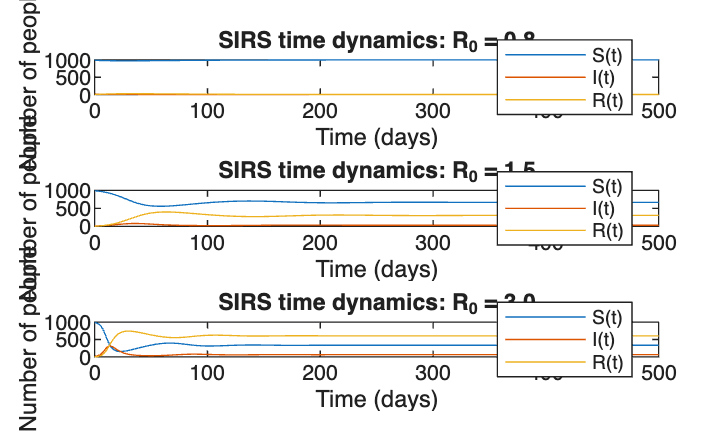

figure
for m = 1:length(R0values)
    R0 = R0values(m);
    beta = R0*gamma/N; 
    [t,x] = ode45(@(t,x) SIRS_ODE(x,beta,gamma,alpha),tspan,x0);

    S = x(:,1);
    I = x(:,2);
    R = x(:,3);

    [Imax,k] = max(I);
    tpeak = t(k);

    subplot(length(R0values),1,m)

    plot(t,S)
    hold on
    plot(t,I)
    plot(t,R)
    xlabel('Time (days)')
    ylabel('Number of people')
    title(sprintf('SIRS time dynamics: R_0 = %.1f',R0))
    legend('S(t)','I(t)','R(t)','Location','best')
end